# Prelab (If student did prelab, 20'')

# Answer the comments, 5'' bonus.

%Type this follwing code to your lab report!!!!!!!!!!!
%Bonus : if you can make proper comments for the blank
% '%' and questions shows below, 
% you will get bonus (max:5'').
H = tf(5,[1 5])


H =
 
    5
  -----
  s + 5
 
Continuous-time transfer function.



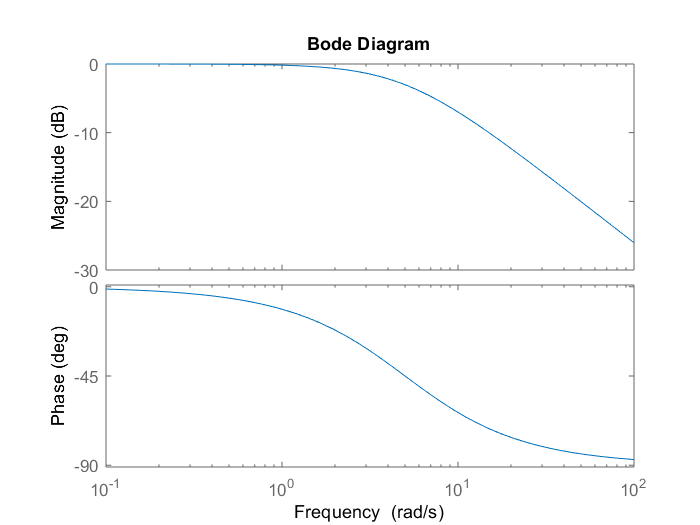

bode(H)

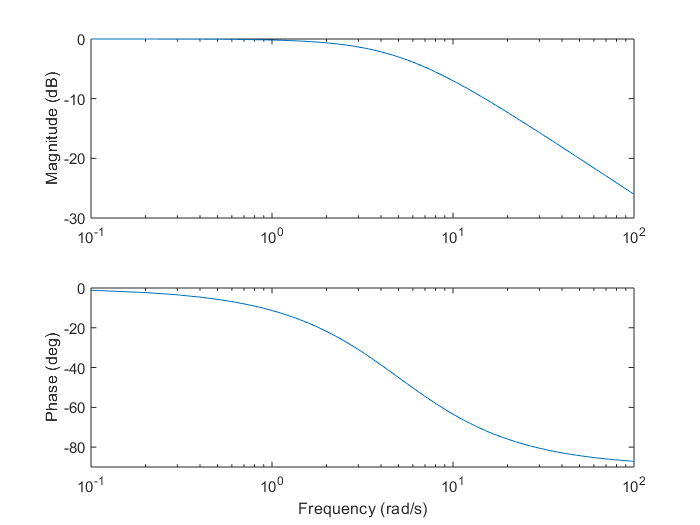

%For proving (c)
w = 0.1:0.1:100;
% Compute magnitude using eqn.(11)
M = 5./sqrt(25+w.^2);
% Compute phase using eqn.(11)
Phi = 180*atan(-0.2*w)/pi;
figure
subplot(211)
% why should we use semilogx and log10 not log?
% Semilogx to uniformize the x-axis to the results in 'bode'
% log10 to compute the DB of M(s)
semilogx(w,20*log10(M));
ylabel('Magnitude (dB)')
xlim([0.1,100])
ylim([-30,0])
subplot(212)
semilogx(w,Phi);
ylim([-90,0])
ylabel('Phase (deg)')
xlabel('Frequency (rad/s)')

# 4.1

# 1  (10'')

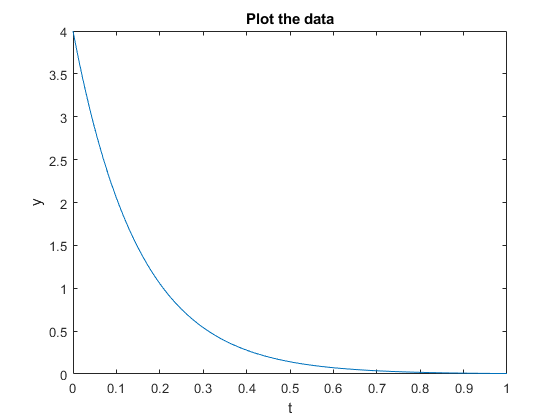

load('EE105_Lab3data.mat')
figure
plot(t,y)
xlabel('t');ylabel('y');
title('Plot the data')

# 2 (20'', 10'' for each method)

In second method, if use code to find the index, **5'' bonus**. If the code only one line, extra **2'' bonus**.

Time constant

%First method
y_tau = 0.37*y(1);
% One line code for index, extra 2'' bonus
index = find(abs(y_tau-y)==min(abs(y_tau-y)),1);
tau_1 = t(index)

tau_1 = 0.1500


%Second method
%Compute dy/dt
dydt = (y(2:101)-y(1:100))./(t(2:101)-t(1:100));
a = dydt./y(1:100);
%You may check a, all the same numbers
tau_2 = 1/(-a(1))

tau_2 = 0.1551

# 4.2 Part 2

# 1.  (15'')

**The model: (5'')**

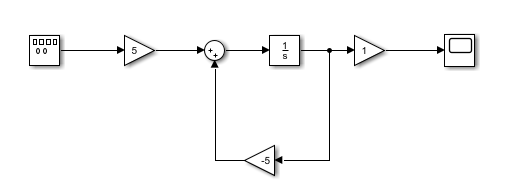

**Output: (10'')**

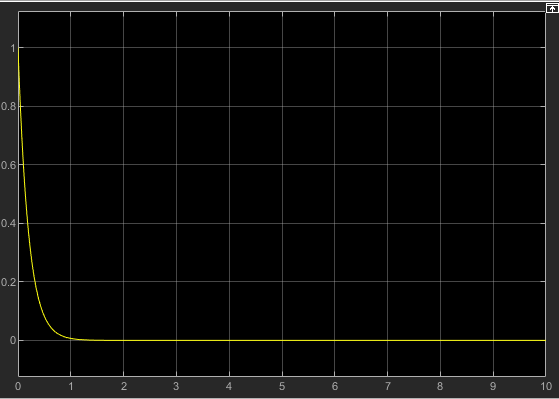

# 2.  (15'')

**The model: (5'')**

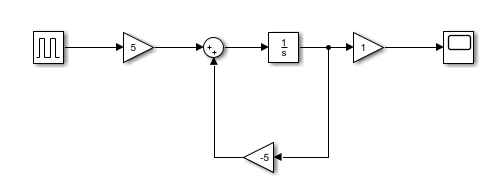

**Output: (5'')**

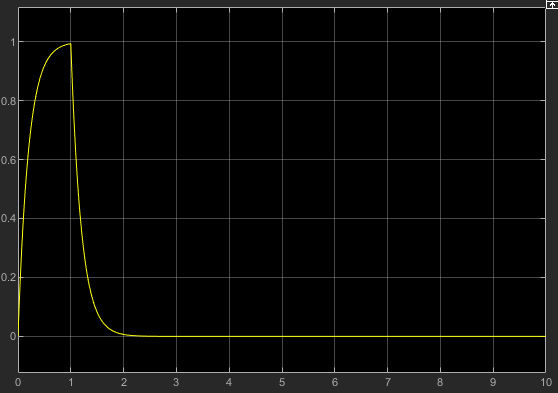

**(c)  (3'') Zoom in the curve, we can fiond it is about 2.8 seconds (If answer greater than 2.5s, that's right) to stable, which greater than the time constan.**

**(d) (2'') Steady state value of y goes to zero. Yes, this match the value prediction.**

# 3.  (20'')

**The model: (5'')**

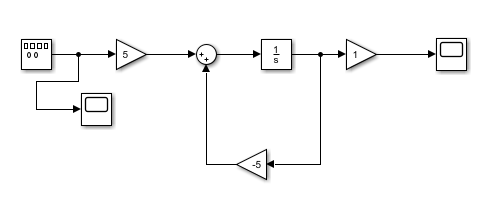

**Output: (5'')**

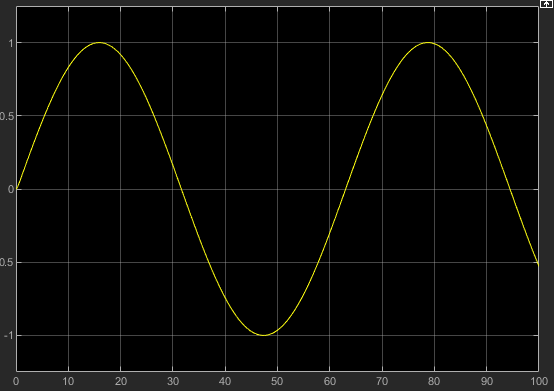

**(d) (2'') The  magnitute of y and u are almost the same, since M(w) = 5/sqrt(25+0.01)=1. Hence, it's match the prediction.**

**(e) (8'', analysis correct: 5'', figure correct: 3'', Have to show the figure) Let's try w = 10. The output as below, M(w) = 5/sqrt(25+100)=0.447, Hence, it's match the prediction.**

**For other results, If w=0, output magnitude should be 1. If w = 1, output magnitude shoould be close to 1 but not over 1 (M = 5/sqrt(26)=0.98). **

**If try w=0.01 again, not points will be graded in this question.**